#   Análisis de la escena desde el panorama

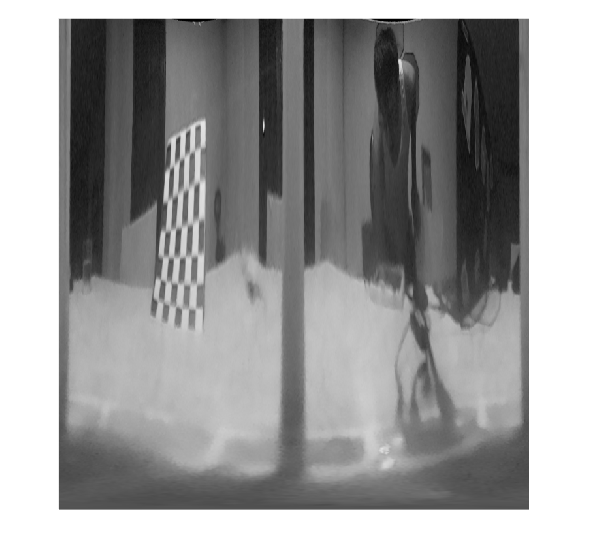

% --- 1) Preprocesado / segmentación rápida del tablero ---
I = imread('img_panorama/cal10_seg_panorama.png');    % tu imagen undistortion+crop
Igray = rgb2gray(I);
figure();
imshow(Igray);

% 1.1) Umbral adaptativo para extraer casillas blancas vs. negras
T = adaptthresh(Igray, 0.5, 'ForegroundPolarity','dark');
BW = imbinarize(Igray, T);

% 1.2) Limpiar con morfología (cerrar huecos y eliminar pequeñas regiones)
se = strel('square', 15);
BW = imclose(BW, se);
BW = bwareaopen(BW, 1000);

% 1.3) Tomar la mayor componente conectada asumimos que es el tablero
CC    = bwconncomp(BW);
stats = regionprops(CC,'Area','BoundingBox');
[~,idx] = max([stats.Area]);
bb     = ceil(stats(idx).BoundingBox);   % [x y w h] del recorte

Iboard = imcrop(Igray, bb);              % recorte en escala de grises
figure();
imshow(Iboard);

% --- 2) Detección de esquinas sólo en la ventana recortada ---
[pts_rel, boardSize] = detectCheckerboardPoints(Iboard);
if isempty(pts_rel)
    warning('Aun no detecta el tablero en recorte #%d.', k);
else
    % Reajustar coordenadas al sistema de I completo
    pts = pts_rel + bb(1:2) - 1;  
    % Ahora puedes usar `pts` y `boardSize` normalmente:
    worldPts = generateCheckerboardPoints(boardSize, squareSize);
    % … seguir con extrinsics, mediciones, etc.
end

% =========================================================================
% Paso 3) Análisis métrico de la escena desde el panorama
% =========================================================================

% 3.1) Leer uno de tus panoramas
panorama = im2uint8(imread('img_panorama/cal10_seg_panorama.png'));

% 3.2) Detectar esquinas del checkerboard en el panorama
[imagePoints, boardSize] = detectCheckerboardPoints(panorama);
if isempty(imagePoints)
    error('No se detectó el tablero en el panorama.');
end

No se detectó el tablero en el panorama.


% 3.3) Generar coordenadas 3D del tablero (en mm, según tu patrón)
squareSize = 30; % mm  ← ¡ajusta al tamaño real de cada casilla!
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% 3.4) Estimar extrínsecos (rotación + traslación)  
%      Esto no lo necesitamos para la distancia en el plano del tablero,
%      pero sirve para verificar la orientación.
[rotVec, transVec] = extrinsics(imagePoints, worldPoints, cameraParams);

% 3.5) Calcular distancia “real” entre dos esquinas conocidas  
%      Por ejemplo, entre la primera esquina y la última
P1 = worldPoints(1,:);             % [0              , 0             , 0]
P2 = worldPoints(end,:);           % [ (cols-1)*sqr  , (rows-1)*sqr , 0]
dist_mm = norm(P1 - P2);           % distancia en milímetros

% 3.6) Visualizar resultados sobre el panorama
figure; imshow(panorama); hold on
plot(imagePoints(:,1), imagePoints(:,2), 'go', 'MarkerSize',8);
text(imagePoints(1,1), imagePoints(1,2),   '  P1','Color','g','FontSize',12);
text(imagePoints(end,1),imagePoints(end,2),'  P2','Color','g','FontSize',12);
title( sprintf( ...
  ['Detección de tablero (', num2str(boardSize(1)),'×',num2str(boardSize(2)),')\n', ...
   'Distancia real P1–P2 = %.1f mm'], dist_mm), ...
  'Interpreter','none' );
